# Analyse combinedModel, input to component contribution

## **Author: Ronan Fleming, NUI Galway, Leiden University**

## **Reviewers: **

## INTRODUCTION

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.

aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'old'];
method = 'remove';
editCobraToolboxPath(basePath,folderPattern,method)

removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/directionalityReport/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/old
removing: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/old


aPath = which('initVonBertalanffy');
basePath = strrep(aPath,'vonBertalanffy/initVonBertalanffy.m','');
addpath(genpath(basePath))
folderPattern=[filesep 'new'];
method = 'add';
editCobraToolboxPath(basePath,folderPattern,method)

adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/componentContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/inchi/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/molFiles/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/protons/new
adding: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/trainingModel/new


initVonBertalanffy

ChemAxon Marvin Beans is installed and working.
	linux-vdso.so.1 (0x00007fff445d9000)
	libc.so.6 => /lib/x86_64-linux-gnu/libc.so.6 (0x00007f91d2049000)
	libopenbabel.so.5 => /usr/lib/libopenbabel.so.5 (0x00007f91d1df9000)
	libstdc++.so.6 => /usr/lib/x86_64-linux-gnu/libstdc++.so.6 (0x00007f91d1bdf000)
	libgcc_s.so.1 => /usr/local/bin/MATLAB/R2021a/sys/os/glnxa64/libgcc_s.so.1 (0x00007f91d19c7000)
	/lib64/ld-linux-x86-64.so.2 (0x00007f91d2269000)
	libdl.so.2 => /lib/x86_64-linux-gnu/libdl.so.2 (0x00007f91d19bf000)
	libz.so.1 => /lib/x86_64-linux-gnu/libz.so.1 (0x00007f91d19a3000)
	libm.so.6 => /lib/x86_64-linux-gnu/libm.so.6 (0x00007f91d1854000)
	libgomp.so.1 => /usr/lib/x86_64-linux-gnu/libgomp.so.1 (0x00007f91d180f000)
	libpthread.so.0 => /lib/x86_64-linux-gnu/libpthread.so.0 (0x00007f91d17ec000)

babel must depend on the system libstdc++.so.6 not the one from MATLAB
Trying to edit the 'LD_LIBRARY_PATH' to make sure that it has the correct system path before the Matlab path!
The solu

Load combined model

load('data_prior_to_componentContribution')

### Statistics on the combined model

fprintf('%u%s\n',nnz(combinedModel.trainingMetBool),' training metabolites')

672 training metabolites


fprintf('%u%s\n',nnz(combinedModel.trainingMetBool & combinedModel.groupDecomposableBool),' of which are Moiety decomposable.')

627 of which are Moiety decomposable.


fprintf('%u%s\n',nnz(combinedModel.trainingMetBool & ~combinedModel.inchiBool),' of which have no inchi.')

45 of which have no inchi.


fprintf('%u%s\n',nnz(combinedModel.trainingMetBool & combinedModel.inchiBool & ~combinedModel.groupDecomposableBool),' of which are not Moiety decomposable.')

0 of which are not Moiety decomposable.


fprintf('%u%s\n',nnz(combinedModel.testMetBool),' test metabolites')

2994 test metabolites


fprintf('%u%s\n',nnz(combinedModel.testMetBool & combinedModel.groupDecomposableBool),' of which are Moiety decomposable.')

1997 of which are Moiety decomposable.


fprintf('%u%s\n',nnz(combinedModel.testMetBool & ~combinedModel.inchiBool),' of which have no inchi.')

994 of which have no inchi.


fprintf('%u%s\n',nnz(combinedModel.testMetBool & combinedModel.inchiBool & ~combinedModel.groupDecomposableBool),' ... of which are not Moiety decomposable.')

3 ... of which are not Moiety decomposable.


fprintf('%u%s\n',size(combinedModel.S,1),' combined model metabolites.')

3666 combined model metabolites.


fprintf('%u%s\n',nnz(combinedModel.trainingMetBool & ~combinedModel.testMetBool),' ... of which are exclusively training metabolites.')

672 ... of which are exclusively training metabolites.


fprintf('%u%s\n',nnz(combinedModel.trainingMetBool & combinedModel.testMetBool),' ... of which are both training and test metabolites.')

0 ... of which are both training and test metabolites.


fprintf('%u%s\n',nnz(~combinedModel.trainingMetBool & combinedModel.testMetBool),' ... of which are exclusively test metabolites.')

2994 ... of which are exclusively test metabolites.


### Sparsity pattern of combinedModel.S

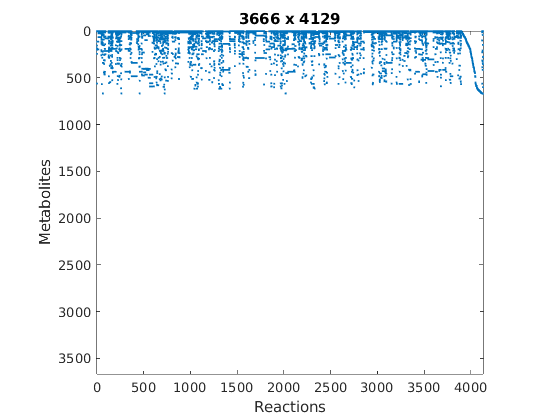

figure
spy(combinedModel.S);
title([int2str(size(combinedModel.S,1)) ' x ' int2str(size(combinedModel.S,2))])
xlabel('Reactions')
ylabel('Metabolites')

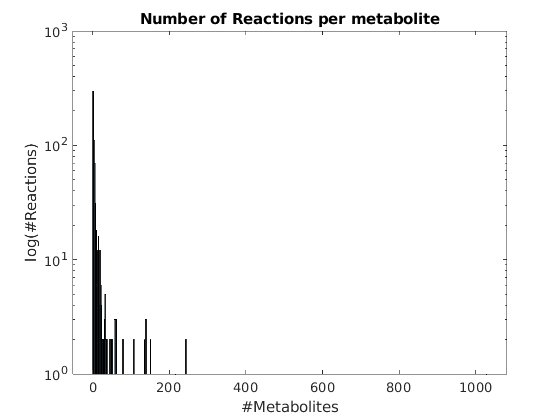

nReactionsPerMetabolite=full(sum(combinedModel.S~=0,2));
histogram(nReactionsPerMetabolite(nReactionsPerMetabolite~=0),'BinWidth',2)
title('Number of Reactions per metabolite')
xlabel('#Metabolites')
ylabel('log(#Reactions)')
set(gca,'YScale','log')

fprintf('%u%s\n',nnz(nReactionsPerMetabolite==0),' metabolites without reactions.')

2998 metabolites without reactions.


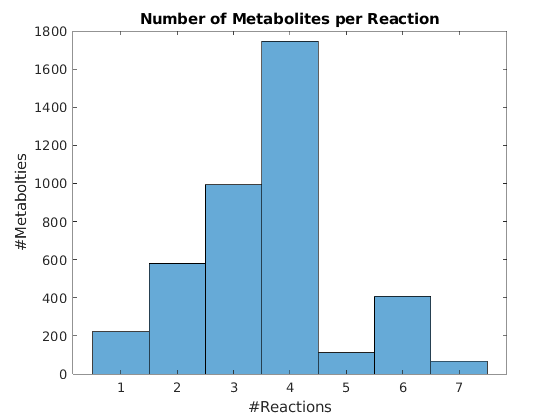

nMetabolitesPerReaction=full(sum(combinedModel.S~=0,1)');
histogram(nMetabolitesPerReaction)
title('Number of Metabolites per Reaction')
xlabel('#Reactions')
ylabel('#Metabolties')

if any(nMetabolitesPerReaction==0)
    error('combinedModel.S reaction without a metabolite')
end

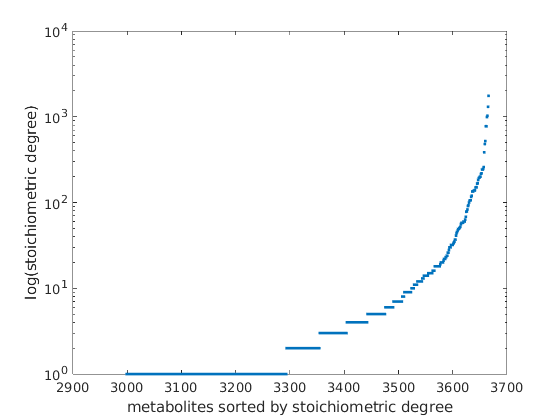

dX = diag(combinedModel.S*combinedModel.S');
figure
plot(sort(dX),'.')
set(gca,'YScale','log')
ylabel('log(stoichiometric degree)')
xlabel('metabolites sorted by stoichiometric degree')

nnz(dX==0)

ans = 2998

### Sparsity pattern of combinedModel.G

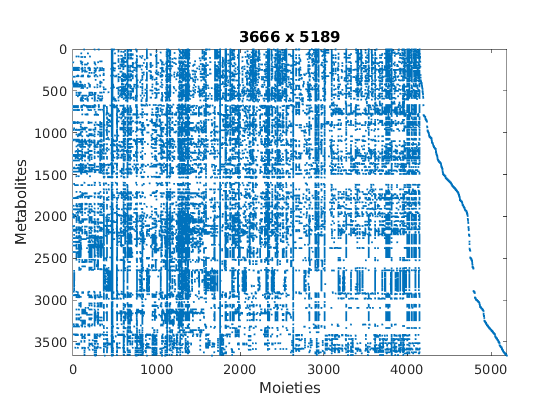

figure
spy(combinedModel.G)
title([int2str(size(combinedModel.G,1)) ' x ' int2str(size(combinedModel.G,2))])
xlabel('Moieties')
ylabel('Metabolites')

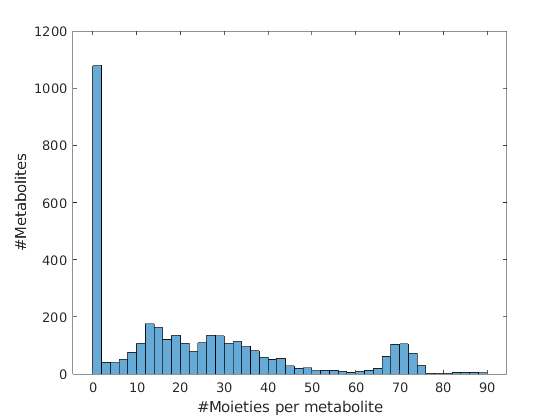

nGroupPerMetabolite = full(sum(combinedModel.G~=0,2));
histogram(nGroupPerMetabolite,'BinWidth',2)
xlabel('#Moieties per metabolite')
ylabel('#Metabolites')

if any(nGroupPerMetabolite==0)
    error('Metabolite without any Moiety')
end

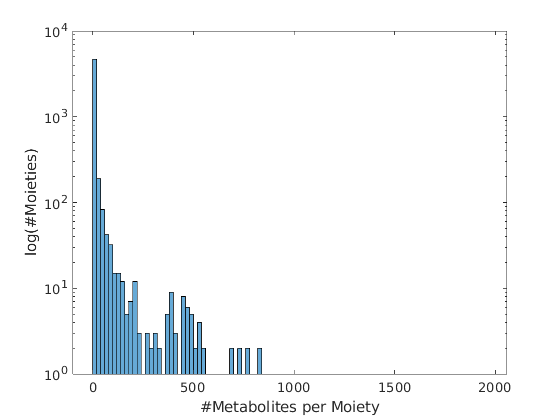

nMetabolitePerGroup = sum(combinedModel.G~=0,1)';
if 0
    histogram(nMetabolitePerGroup);
    %set(gca,'YScale','log')
    ylim([0, 10]);
else
    histogram(nMetabolitePerGroup);
    set(gca,'YScale','log')
end
xlabel('#Metabolites per Moiety')
ylabel('log(#Moieties)')

if any(nMetabolitePerGroup==0)
    error('Moiety without metabolite')
end

### Sparsity pattern of combinedModel.StG

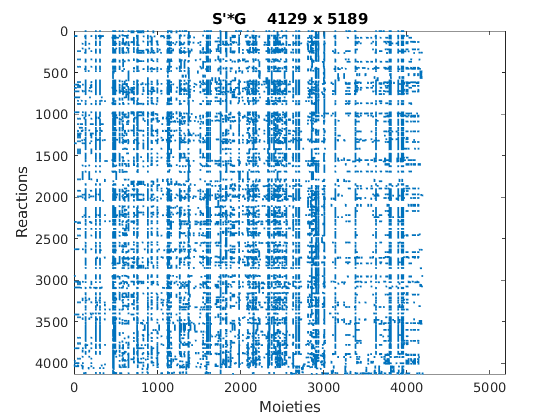

StG=combinedModel.S'*combinedModel.G;
figure
spy(StG)
title(['S''*G    ' int2str(size(StG,1)) ' x ' int2str(size(StG,2))])
xlabel('Moieties')
ylabel('Reactions')

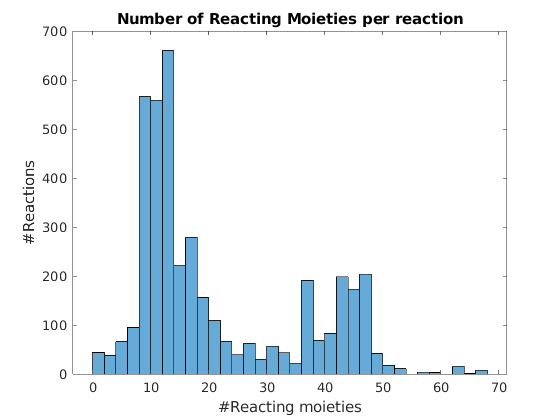

nReactingMoieties=full(sum(StG~=0,2));
histogram(nReactingMoieties,'BinWidth',2)
title('Number of Reacting Moieties per reaction')
xlabel('#Reacting moieties')
ylabel('#Reactions')

fprintf('%u%s\n',nnz(nReactingMoieties==0),' reactions without reacting moieties.')

19 reactions without reacting moieties.


printRxnFormula(combinedModel,combinedModel.rxns(nReactingMoieties==0));

TECRDB_373	C00002 + C00015 	->	C00008 + C00075 
TECRDB_764	C00004 + C00006 	->	C00003 + C00005 
TECRDB_765	C00004 + C00006 	->	C00003 + C00005 
TECRDB_766	C00004 + C00006 	->	C00003 + C00005 
TECRDB_767	C00004 + C00006 	->	C00003 + C00005 
TECRDB_768	C00004 + C00006 	->	C00003 + C00005 
TECRDB_769	C00004 + C00006 	->	C00003 + C00005 
TECRDB_770	C00004 + C00006 	->	C00003 + C00005 
TECRDB_771	C00004 + C00006 	->	C00003 + C00005 
TECRDB_772	C00004 + C00006 	->	C00003 + C00005 
TECRDB_773	C00004 + C00006 	->	C00003 + C00005 
TECRDB_822	C00003 + C00005 	->	C00004 + C00006 
TECRDB_823	C00003 + C00005 	->	C00004 + C00006 
TECRDB_824	C00003 + C00005 	->	C00004 + C00006 
TECRDB_2364	C00002 + C00015 	->	C00008 + C00075 
TECRDB_2521	C00002 + C00035 	->	C00008 + C00044 
TECRDB_2639	C00002 + C00104 	->	C00008 + C00081 
TECRDB_2870	C00166 	->	C02763 
TECRDB_3904	C00036 	->	C03981 


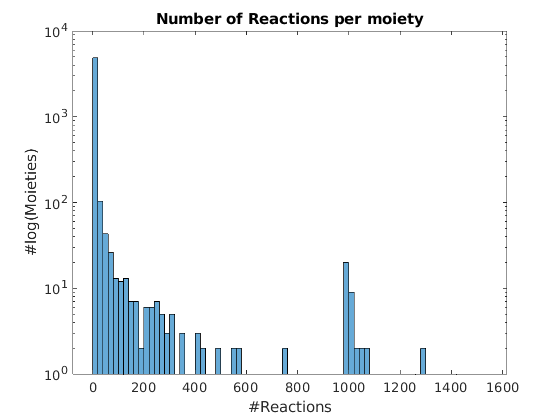

nReactionsPerMoiety=full(sum(StG~=0,1)');
histogram(nReactionsPerMoiety)
set(gca,'YScale','log')
title('Number of Reactions per moiety')
xlabel('#Reactions')
ylabel('#log(Moieties)')

fprintf('%u%s%u%s\n',nnz(nReactionsPerMoiety==0),' of the ', length(nReactionsPerMoiety), ' moieties do not react in any training reaction.')

3789 of the 5189 moieties do not react in any training reaction.
